klasyczny” eksperyment Zieglera - Nicholsa. 

P = 1; I = 0; D = 0;

figure;
hold on;
PIDtest();
P=2;
PIDtest();
P=3.35;
PIDtest();
legend(["kp = 1" "kp = 2" "kp = 3.4"])
hold off;

%[czas, y] = ginput(2)
T = 167.0221 - 90.884

T = 76.1381

kkryt = 3.3

kkryt = 3.3000

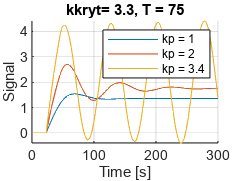

title("kkryt= 3.3, T = 75")


figure;
hold on;
P = 0.5 * kkryt

P = 1.6500

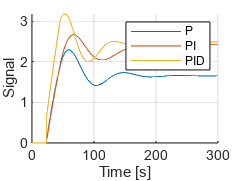

PIDtest();
P= 0.45 * kkryt; I = 1/(0.85*T);
PIDtest();
P= 0.6 * kkryt; I = 1/(0.5*T); D = 0.12*T;
PIDtest();
legend(["P" "PI" "PID"])
hold off;

Dostrajanie regulatora PID metodą Astroma-Hagglunda.

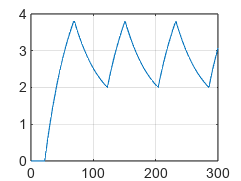

figure;
out = sim("model.slx");
plot(out.RScopeData1.time, out.RScopeData1.signals.values);
grid on;

u = 4;
A = 1.7;
kkryt = 4*u/(pi * A)

kkryt = 2.9959

T = 80;

figure;
hold on;
P = 0.5 * kkryt

P = 1.4979

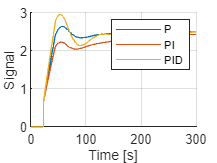

PIDtest();
P= 0.45 * kkryt; I = 1/(0.85*T);
PIDtest();
P= 0.6 * kkryt; I = 1/(0.5*T); D = 0.12*T;
PIDtest();
legend(["P" "PI" "PID"])
hold off;

Dostrajanie regulatora PID na podstawie parametrów transmitancji zastępczej

k = 1.18 Tob = 45; tau = 22;
kkryt = 0.95/(T/tau)
I = 1/(2.4*tau)
D = 0.5 * tau
figure
PIDtest()



Użycie funkcji „Autotune” dostępnej w środowisku SIMULINK

function [] = PIDtest()
    pidsim = sim("model.slx");
    plot(pidsim.PIDScopeData.time, pidsim.PIDScopeData.signals.values)
    xlabel("Time [s]")
    ylabel("Signal")
    grid on;
end